%% Configuración inicial
clear all; close all; clc;

% Parámetros del solenoide
nL = 5;         % Número de espiras
N = 30;          % Puntos por espira
R = 1.0;         % Radio de las espiras (m)
sz = 0.5;        % Separación entre espiras (m)
I = 300;         % Corriente (A)
mu0 = 4*pi*1e-7; % Permeabilidad magnética del vacío
km = mu0 * I / (4*pi); % Constante de Biot-Savart

%% Creación del grid espacial
% Definimos el volumen donde calcularemos el campo
x = linspace(-3, 3, 30); % Eje X
y = linspace(-3, 3, 30); % Eje Y (solo necesitamos y=0 para simetría axial)
z = linspace(-2, nL*sz+2, 40); % Eje Z (cubre todo el solenoide + margen)

% Creamos el grid 3D
[X, Y, Z] = meshgrid(x, y, z);

% Inicialización de matrices para componentes del campo
Bx = zeros(size(X));
By = zeros(size(Y));
Bz = zeros(size(Z));

%% Creación de las espiras
theta = linspace(0, 2*pi, N+1);
theta = theta(1:end-1); % Eliminar punto duplicado
dtheta = theta(2) - theta(1);

% Pre-alocación para coordenadas de las espiras
espira_x = zeros(nL, N);
espira_y = zeros(nL, N);
espira_z = zeros(nL, N);
dl_x = zeros(nL, N);
dl_y = zeros(nL, N);

for k = 1:nL
    % Posiciones de los puntos en la espira k
    espira_x(k,:) = R * cos(theta);
    espira_y(k,:) = R * sin(theta);
    espira_z(k,:) = (k-1)*sz * ones(1,N);
    
    % Diferenciales de línea (dl)
    dl_x(k,:) = -R * sin(theta) * dtheta;
    dl_y(k,:) = R * cos(theta) * dtheta;
end

%% Cálculo del campo magnético (Ley de Biot-Savart)
fprintf('Calculando campo magnético...\n');

Calculando campo magnético...


tic; % Iniciar cronómetro

% Vectorizamos los puntos de las espiras
all_espira_x = espira_x(:);
all_espira_y = espira_y(:);
all_espira_z = espira_z(:);
all_dl_x = dl_x(:);
all_dl_y = dl_y(:);

% Tamaño del grid
[ny, nx, nz] = size(X);

% Calculamos el campo para cada punto del grid
for i = 1:ny
    for j = 1:nx
        for k = 1:nz
            % Vector desde el punto de la espira al punto de observación
            rx = X(i,j,k) - all_espira_x;
            ry = Y(i,j,k) - all_espira_y;
            rz = Z(i,j,k) - all_espira_z;
            
            % Distancia al cubo
            r3 = (rx.^2 + ry.^2 + rz.^2).^(3/2);
            r3(r3 < (0.1*R)^3) = Inf; % Evitar singularidades
            
            % Producto cruz dl × r
            cross_x = all_dl_y .* rz; % dl_y * rz - dl_z * ry (dl_z = 0)
            cross_y = -all_dl_x .* rz; % dl_z * rx - dl_x * rz (dl_z = 0)
            cross_z = all_dl_x .* ry - all_dl_y .* rx;
            
            % Contribución de todos los elementos de corriente
            Bx(i,j,k) = km * sum(cross_x ./ r3);
            By(i,j,k) = km * sum(cross_y ./ r3);
            Bz(i,j,k) = km * sum(cross_z ./ r3);
        end
    end
    fprintf('Progreso: %.1f%%\n', 100*i/ny);
end

Progreso: 3.3%
Progreso: 6.7%
Progreso: 10.0%
Progreso: 13.3%
Progreso: 16.7%
Progreso: 20.0%
Progreso: 23.3%
Progreso: 26.7%
Progreso: 30.0%
Progreso: 33.3%
Progreso: 36.7%
Progreso: 40.0%
Progreso: 43.3%
Progreso: 46.7%
Progreso: 50.0%
Progreso: 53.3%
Progreso: 56.7%
Progreso: 60.0%
Progreso: 63.3%
Progreso: 66.7%
Progreso: 70.0%
Progreso: 73.3%
Progreso: 76.7%
Progreso: 80.0%
Progreso: 83.3%
Progreso: 86.7%
Progreso: 90.0%
Progreso: 93.3%
Progreso: 96.7%
Progreso: 100.0%



toc; % Mostrar tiempo de cálculo

Elapsed time is 1.496100 seconds.


fprintf('Cálculo completado.\n');

Cálculo completado.


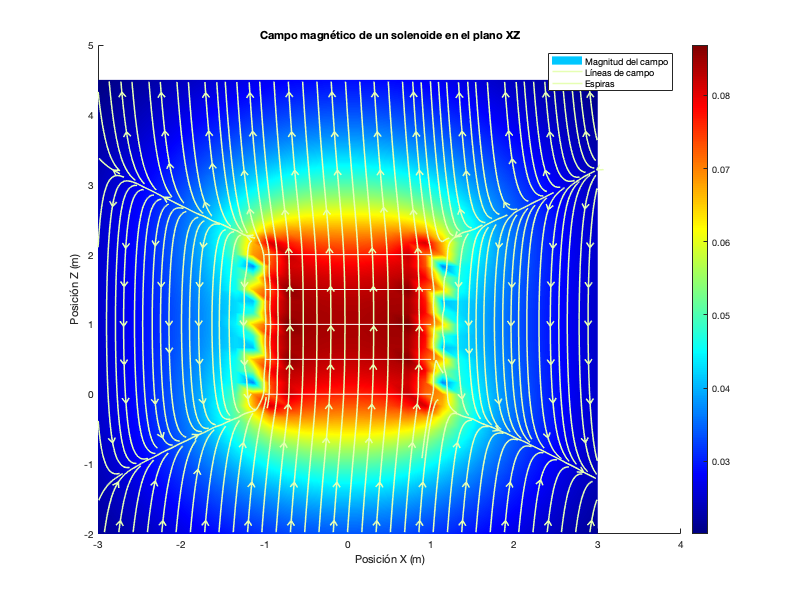


%% Visualización en el plano XZ (y=0)
centery = round(ny/2); % Índice central (y ≈ 0)

% Extraemos las componentes en el plano XZ
Bx_xz = squeeze(Bx(:,centery,:));
By_xz = squeeze(By(:,centery,:));
Bz_xz = squeeze(Bz(:,centery,:));
Bmag_xz = sqrt(Bx_xz.^2 + By_xz.^2 + Bz_xz.^2);

% Crear figura
figure(1);
set(gcf, 'Position', [100 100 800 600]);
hold on;

% Mapa de calor de la magnitud del campo
pcolor(x, z, (Bmag_xz').^(1/3)); % Transponer y suavizar con raíz cúbica
shading interp;
colormap(jet);
colorbar;
title('Magnitud del campo magnético (|B|^{1/3})');
xlabel('Posición X (m)');
ylabel('Posición Z (m)');

% Líneas de campo magnético
h = streamslice(x, z, Bx_xz', Bz_xz', 3);
set(h, 'Color', [0.9 1 0.7], 'LineWidth', 1.5);

% Dibujar las espiras
for k = 1:nL
    z_pos = (k-1)*sz;
    plot(R*cos(linspace(0,2*pi,100)), z_pos + 0*linspace(0,2*pi,100), 'w-', 'LineWidth', 1);
    plot([-R R], [z_pos z_pos], 'w--'); % Línea que representa la espira
end

% Añadir título y leyenda
title('Campo magnético de un solenoide en el plano XZ');
legend('Magnitud del campo', 'Líneas de campo', 'Espiras', 'Location', 'northeast');

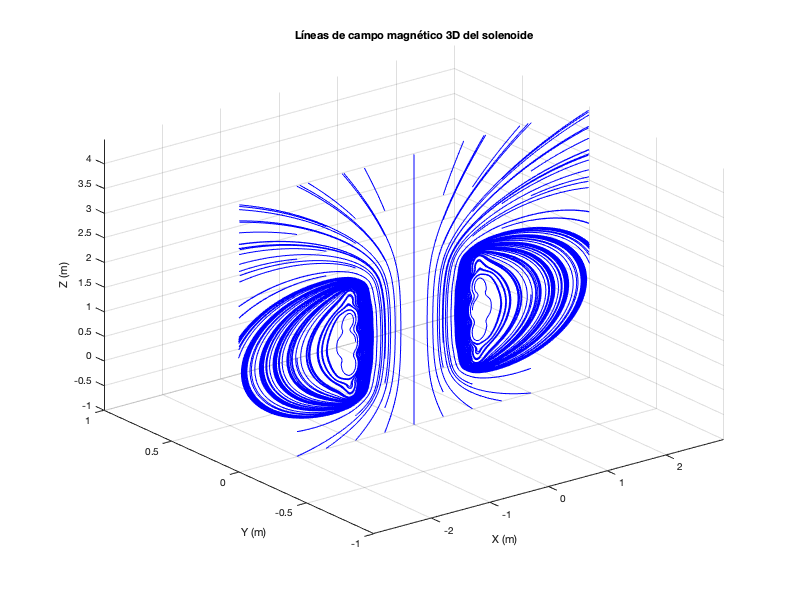


%% Visualización 3D de líneas de campo
figure(2);
set(gcf, 'Position', [100 100 800 600]);

% Seleccionar puntos de inicio para las líneas de campo
startx = -2:0.5:2;
starty = zeros(size(startx));
startz = -1:0.5:nL*sz+1;

% Convertir a grid para streamline
[StartX, StartY, StartZ] = meshgrid(startx, starty, startz);

% Dibujar líneas de campo 3D
streamline(stream3(x, y, z, Bx, By, Bz, StartX, StartY, StartZ));

% Configuración de la figura
axis tight;
grid on;
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
title('Líneas de campo magnético 3D del solenoide');
view(3);
rotate3d on;